clc; clearvars;

tempo_path = "C:\NERTO_drive\TEMPO_data";
tropomi_path = "C:\NERTO_drive\TROPOMI_data";
% merged_path = "C:\NERTO_drive\merged_data_ams";
merged_path = "C:\NERTO_drive\merged_test";

tempo_files = tempo_table(tempo_path);
tropomi_files = tropomi_table(tropomi_path);
merged_files = merged_table(merged_path);

% save_folder = 'C:/NERTO_drive/average_data_ams';
save_folder = 'C:/NERTO_drive/average_data_test';

if ~exist(save_folder, "dir")
    mkdir(save_folder)
end

pandora_coords = [[40.8153, -73.9505];[40.8679, -73.8781];[40.7361, -73.8215];[39.0553, -76.8783];[39.3109, -76.4745];[38.9926, -76.8396];[38.9218, -77.0124];[40.4622, -74.4294];[41.3014, -72.9029];[41.8213, -73.2973];[41.2568, -72.5533];];
pandora_names = ["CCNY" "NYBG" "Queens College" "Beltsville" "Essex" "Greenbelt" "DC" "New Brunswick" "New Haven" "Cornwall"];

start_day = datetime("2023-08-01", "InputFormat", "uuuu-MM-dd"); start_day.TimeZone = 'UTC';
end_day =   datetime("2023-09-01", "InputFormat", "uuuu-MM-dd"); end_day.TimeZone = 'UTC';

process = true;
overwrite = false;

months = month(start_day:end_day);
years = year(start_day:end_day);

s = unique([months' years'], "rows", "stable");

if process == true
    parfor i = 1:size(s,1)-1
        temp_start_day = datetime(s(i,2),s(i,1),1,'TimeZone','UTC');
        temp_end_day = datetime(s(i+1,2),s(i+1,1),1, 'TimeZone','UTC');
    
        tempo_files_avg = tempo_files(tempo_files.Date>=temp_start_day & tempo_files.Date<temp_end_day,:);
        tropomi_files_avg = tropomi_files(tropomi_files.Date>=temp_start_day & tropomi_files.Date<temp_end_day,:);
        merged_files_avg = merged_files(merged_files.Date>=temp_start_day & merged_files.Date<temp_end_day,:);
    
        m = month(temp_start_day);
        y = year(temp_start_day);
        tempo_save_name = fullfile(save_folder,['TEMPO_AVG_', num2str(m), '_', num2str(y),'.mat']);
        tropomi_save_name = fullfile(save_folder,['TROPOMI_AVG_', num2str(m), '_', num2str(y),'.mat']);
        merged_save_name = fullfile(save_folder,['MERGED_AVG_', num2str(m), '_', num2str(y),'.mat']);
    
        disp(['Averaging tempo ', char(string(temp_start_day)), ' to ', char(string(temp_end_day-days(1)))])
        process_avg(tempo_files_avg.Filename, tempo_save_name, 'tempo', overwrite);
    
        disp(['Averaging tropomi ', char(string(temp_start_day)), ' to ', char(string(temp_end_day-days(1)))])
        process_avg(tropomi_files_avg.Filename, tropomi_save_name, 'tropomi', overwrite);
    
        disp(['Averaging merged ', char(string(temp_start_day)), ' to ', char(string(temp_end_day-days(1)))])
        process_avg(merged_files_avg.Filename, merged_save_name, 'merged', overwrite);
    end
end

Averaging tempo 01-Aug-2023 to 31-Aug-2023
File already exists
Averaging tropomi 01-Aug-2023 to 31-Aug-2023
File already exists
Averaging merged 01-Aug-2023 to 31-Aug-2023
File already exists


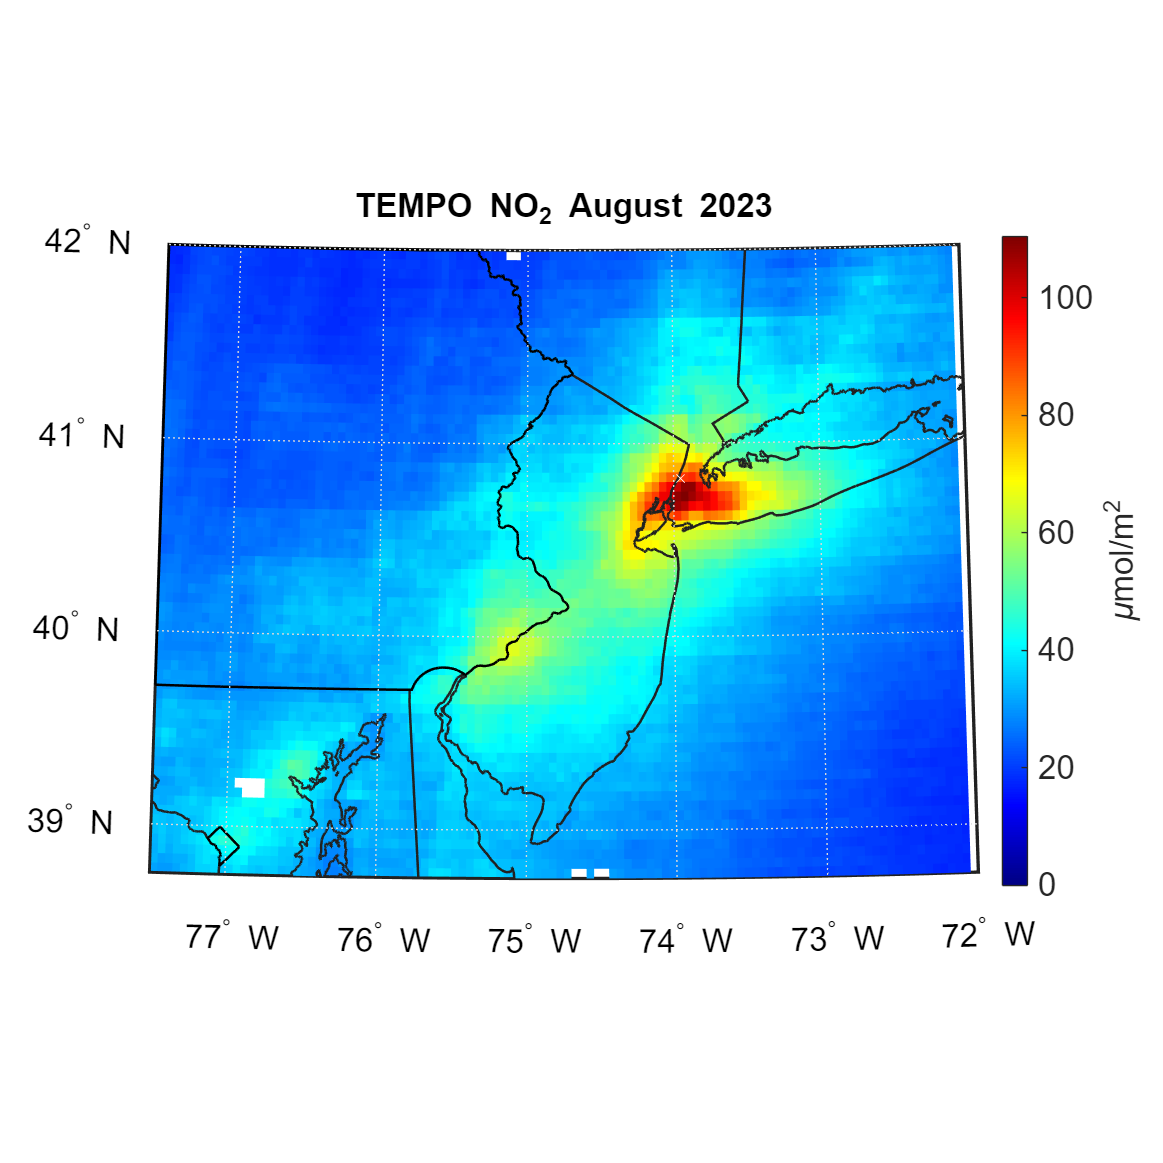

this_year = "2023";
this_month = "8";

lat_bounds = [38.75 42];
lon_bounds = [-77.5 -72];

color_lim =      [0 100];
color_lim_diff = [-20 20];
color_lim_u = [0 25];

c_lim_auto = true;
save_fig = true;

c = [num2str(this_month),'_',num2str(this_year)];
US_states = readgeotable('cb_2023_us_state_500k.shp');
lw = 1.5;
font_size = 20;
% resolution = 300;
USA = load("./misc/USA.mat");
USA = USA.USA;
cb_str = '\mumol/m^2';
m_color = 'w';
m_shp = 'x';
m_size = 50;

dt = datetime(double(this_year),double(this_month),1);
month_str = month(dt, 'name');

avg_files = dir([save_folder,'/*.mat']);
fig_folder = 'C:/NERTO_drive/figures_test';

if ~exist(fig_folder, "dir")
    mkdir(fig_folder)
end

month_files = avg_files(contains({avg_files.name}, c),:);

tempo_file = month_files(contains({month_files.name}, 'TEMPO'),:);
tropomi_file = month_files(contains({month_files.name}, 'TROPOMI'),:);
merged_file = month_files(contains({month_files.name}, 'MERGED'),:);

tempo_data = load(fullfile(tempo_file.folder,tempo_file.name));
tropomi_data = load(fullfile(tropomi_file.folder,tropomi_file.name));
merged_data = load(fullfile(merged_file.folder,merged_file.name));

tempo_data.no2_interp = tempo_data.no2_interp .* 10^6 ./ conversion_factor('trop-tempo');
tempo_data.no2_u_interp = tempo_data.no2_u_interp .* 10^6 ./ conversion_factor('trop-tempo');

tropomi_data.no2_interp = tropomi_data.no2_interp .* 10^6;
tropomi_data.no2_u_interp = tropomi_data.no2_u_interp .* 10^6;

merged_data.no2_interp = merged_data.no2_interp .* 10^6;
merged_data.no2_u_interp = merged_data.no2_u_interp .* 10^6;

merged_data.update_interp = merged_data.update_interp .* 10^6;

in_bounds = tempo_data.lat_grid>=lat_bounds(1) & tempo_data.lat_grid<=lat_bounds(2) & tempo_data.lon_grid>=lon_bounds(1) & tempo_data.lon_grid<=lon_bounds(2);

if c_lim_auto == true
    color_lim(2) = max([tempo_data.no2_interp(in_bounds) tropomi_data.no2_interp(in_bounds) merged_data.no2_interp(in_bounds)], [], 'all');
    color_lim_diff(1) = min(merged_data.update_interp(in_bounds), [],"all");
    color_lim_diff(2) = max(merged_data.update_interp(in_bounds), [],"all");
end

dim = [0 0 1000 1000];
figure('Position', dim);
usamap(lat_bounds,lon_bounds)
surfm(tempo_data.lat_grid,tempo_data.lon_grid,tempo_data.no2_interp)
geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
scatterm(pandora_coords(1,1),pandora_coords(1,2), m_size, m_color,m_shp)

title(['TEMPO NO_{2} ', char(month_str), ' ', num2str(this_year)])
cb = colorbar;
colormap('jet')
ax = gca;
ax.CLim = color_lim;
cb.Label.String = cb_str;
fontsize(font_size,"points")
if save_fig == true
    exportgraphics(gcf, fullfile(fig_folder,'./tempo.png'))
end

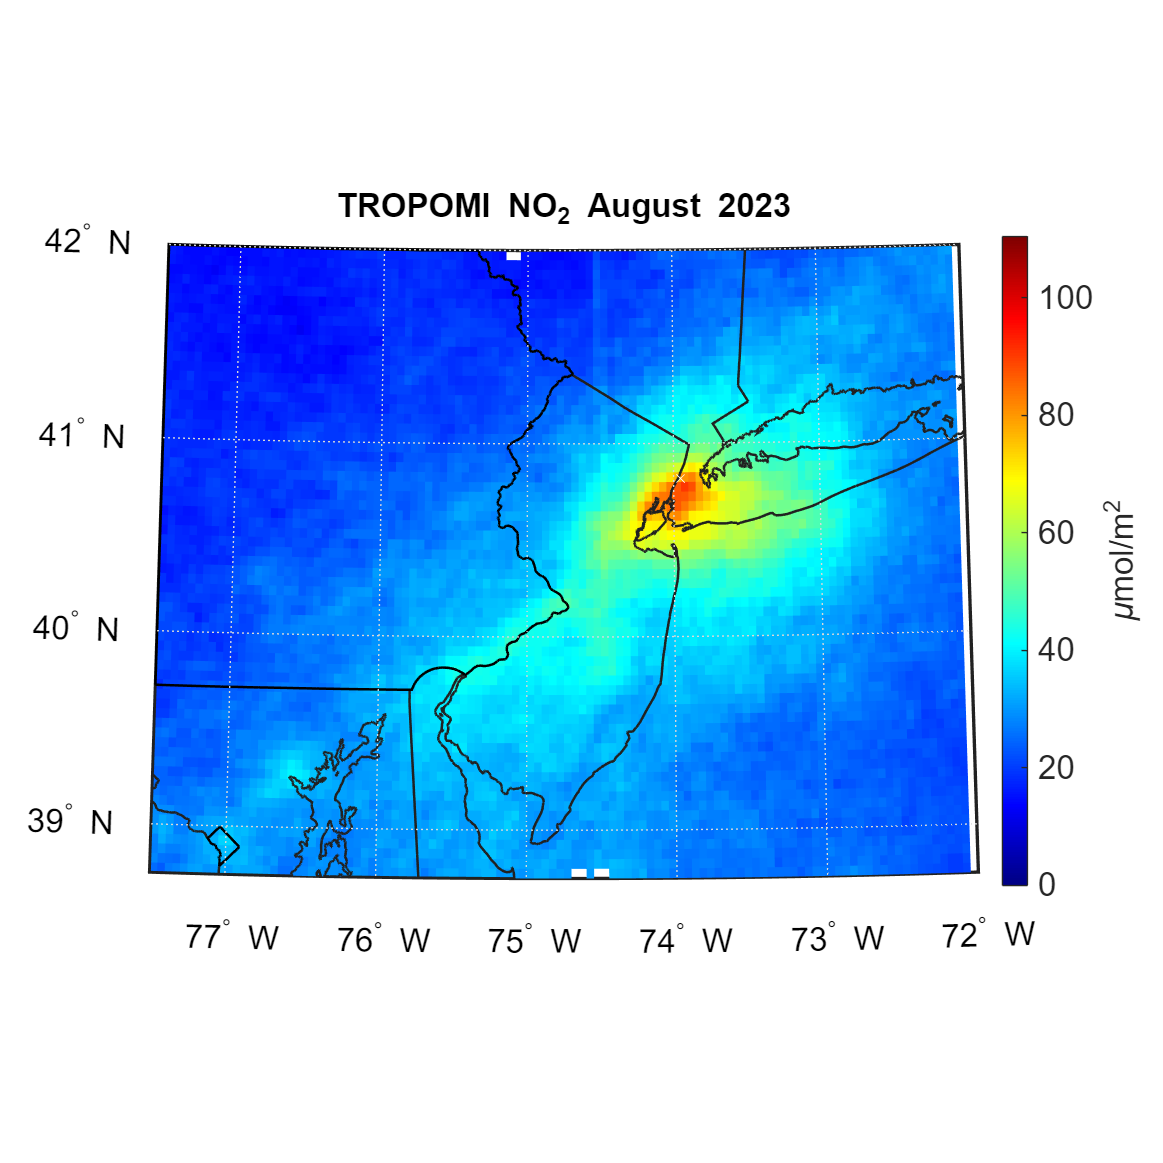


figure('Position', dim);
usamap(lat_bounds,lon_bounds)
surfm(tropomi_data.lat_grid,tropomi_data.lon_grid,tropomi_data.no2_interp)
geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
scatterm(pandora_coords(1,1),pandora_coords(1,2), m_size, m_color,m_shp)
title(['TROPOMI NO_{2} ', char(month_str), ' ', num2str(this_year)])
cb = colorbar;
colormap('jet')
ax = gca;
ax.CLim = color_lim;
cb.Label.String = cb_str;
fontsize(font_size,"points")
if save_fig == true
    exportgraphics(gcf, fullfile(fig_folder,'./tropomi.png'))
end

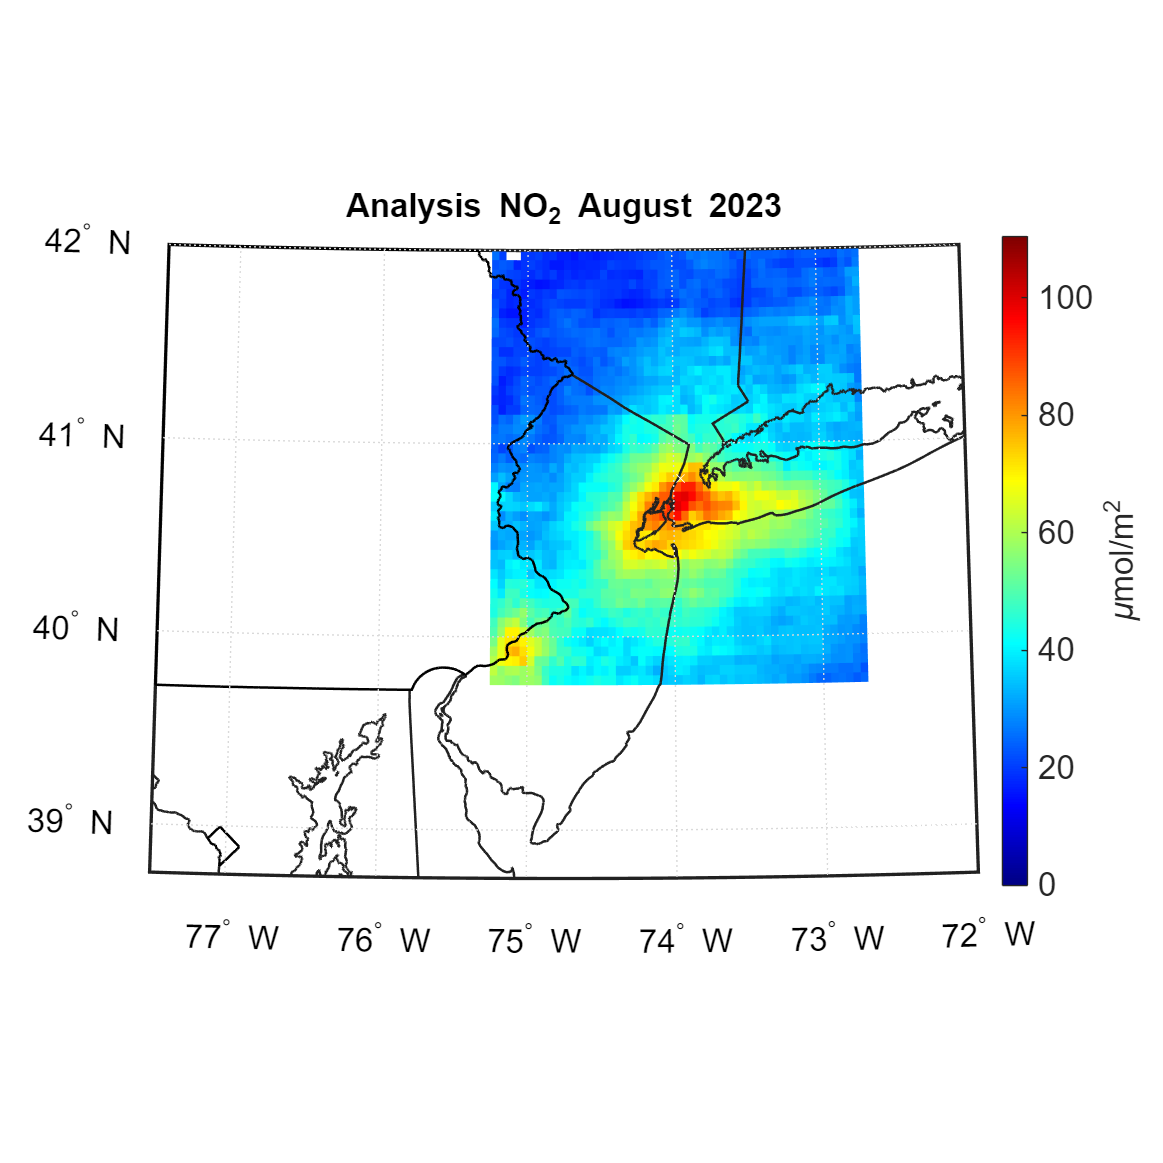


figure('Position', dim);
usamap(lat_bounds,lon_bounds)
surfm(merged_data.lat_grid,merged_data.lon_grid,merged_data.no2_interp)
geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
scatterm(pandora_coords(1,1),pandora_coords(1,2), m_size, m_color,m_shp)
title(['Analysis NO_{2} ', char(month_str), ' ', num2str(this_year)])
cb = colorbar;
colormap('jet')
ax = gca;
ax.CLim = color_lim;
cb.Label.String = cb_str;
fontsize(font_size,"points")
if save_fig == true
    exportgraphics(gcf, fullfile(fig_folder,'./merged.png'))
end

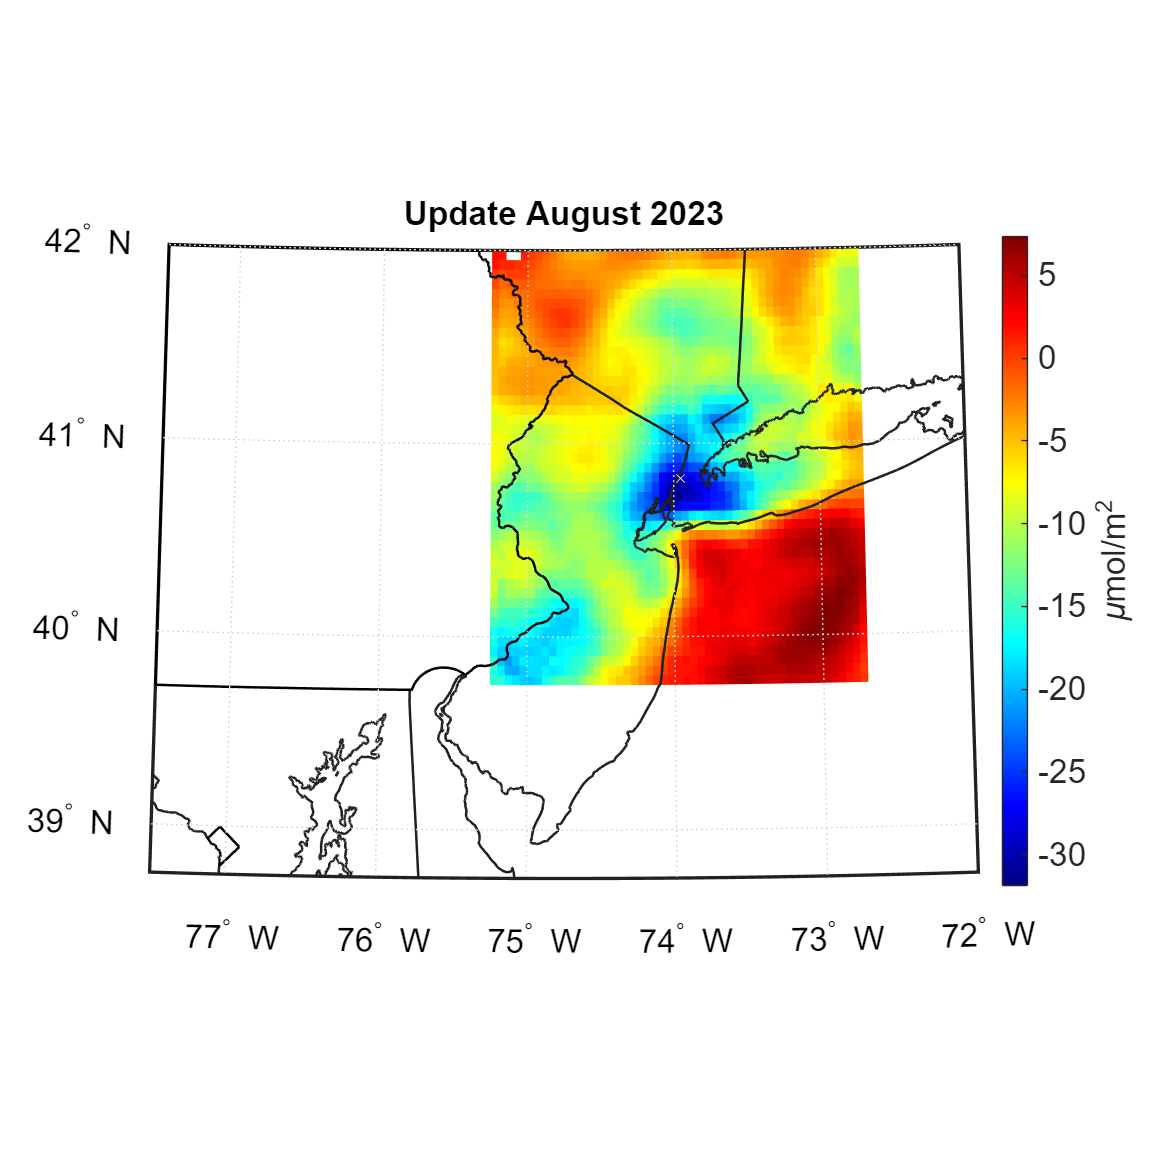


figure('Position', dim);
usamap(lat_bounds,lon_bounds)
surfm(merged_data.lat_grid,merged_data.lon_grid, merged_data.update_interp)
geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
scatterm(pandora_coords(1,1),pandora_coords(1,2), m_size, m_color,m_shp)
title(['Update ', char(month_str), ' ', num2str(this_year)])
cb = colorbar;
colormap('jet')
ax = gca;
ax.CLim = color_lim_diff;
cb.Label.String = cb_str;
fontsize(font_size,"points")
if save_fig == true
    exportgraphics(gcf, fullfile(fig_folder,'./update.png'))
end

## Plots of NO2 uncertainty

figure;
usamap(lat_bounds,lon_bounds)
surfm(tempo_data.lat_grid,tempo_data.lon_grid,tempo_data.no2_u_interp)
geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
title([num2str(this_month), '_', num2str(this_year), ' Avg. TEMPO NO_{2} Uncertainty'])
cb = colorbar;
colormap('jet')
ax = gca;
ax.CLim = color_lim_u;
cb.Label.String = cb_str;
fontsize(font_size,"points")

figure;
usamap(lat_bounds,lon_bounds)
surfm(tropomi_data.lat_grid,tropomi_data.lon_grid,tropomi_data.no2_u_interp)
geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
title([num2str(this_month), '_', num2str(this_year), ' Avg. TROPOMI NO_{2} Uncertainty'])
cb = colorbar;
colormap('jet')
ax = gca;
ax.CLim = color_lim_u;
cb.Label.String = cb_str;
fontsize(font_size,"points")

figure;
usamap(lat_bounds,lon_bounds)
surfm(merged_data.lat_grid,merged_data.lon_grid,merged_data.no2_u_interp)
geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
title([num2str(this_month), '_', num2str(this_year), ' Avg. Merged NO_{2} Uncertainty'])
cb = colorbar;
colormap('jet')
ax = gca;
ax.CLim = color_lim_u;
cb.Label.String = cb_str;
fontsize(font_size,"points")